% Data
time = [0 5 10 15 20 25 30 35 40 45 50 55]; % Time elapsed in minutes
pressure = [98.8 62.9 39.8 24.7 15.1 9.3 5.8 3.6 2.2 1.35 0.9 0.61]; % Pressure in kPa

% Exponential decay function: P = A * exp(-k * t)
% Fit exponential decay curve to the data
ft = fittype('A*exp(-k*t)', 'independent', 't', 'dependent', 'P');
opts = fitoptions('Method', 'NonlinearLeastSquares');
opts.StartPoint = [max(pressure), 0.1]; % Initial guess for A and k

% Perform the fit
[fitResult, gof] = fit(time(:), pressure(:), ft, opts);

% Display fit parameters
disp('Fit Parameters:');

Fit Parameters:


disp(fitResult);

     General model:
     fitResult(t) = A*exp(-k*t)
     Coefficients (with 95% confidence bounds):
       A =       99.19  (98.43, 99.96)
       k =     0.09272  (0.09147, 0.09398)


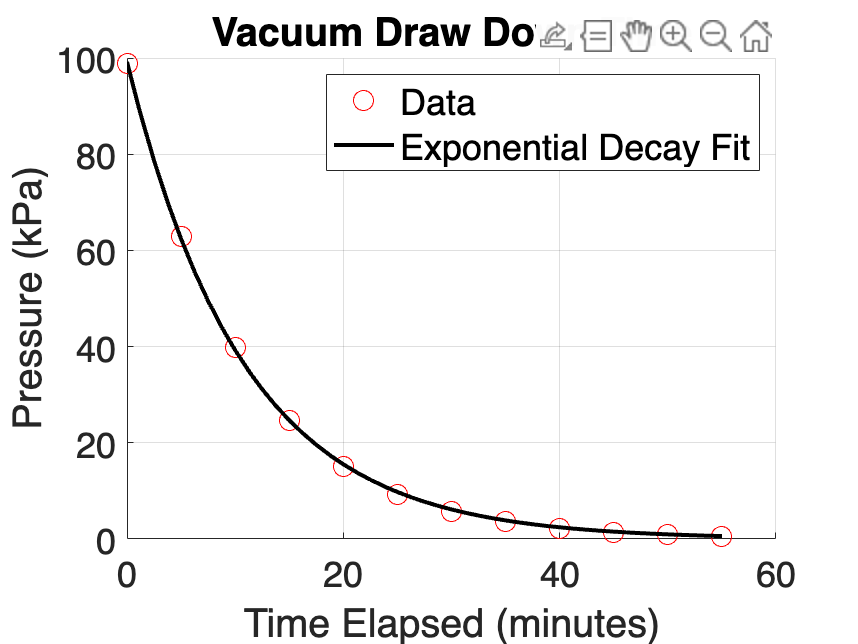


% Plot the data and the fitted curve
figure;
hold on;
plot(time, pressure, 'ro','MarkerSize', 10); % Plot data points
fplot(@(t) fitResult.A * exp(-fitResult.k * t), [0, 55], 'k-', 'LineWidth', 2); % Plot fitted curve

% Formatting the plot
title('Vacuum Draw Down Time', 'FontSize', 18);
xlabel('Time Elapsed (minutes)', 'FontSize', 18);
ylabel('Pressure (kPa)', 'FontSize', 18);
legend('Data', 'Exponential Decay Fit', 'FontSize', 18);
grid on;

% Set font size for the axes labels and title
set(gca, 'FontSize', 18);